# 1. Processat + Segmentació + Etiquetat + Descripció de regions

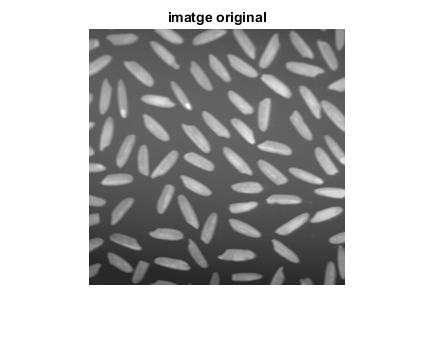

clear,close all
orig = imread ('arros.tif');
imshow(orig), title('imatge original')

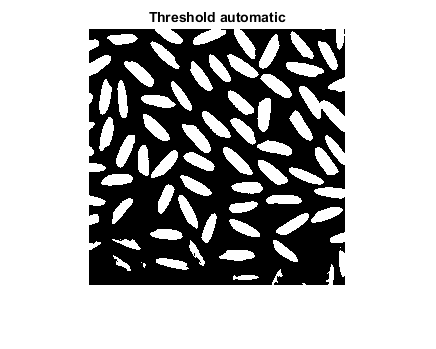


% segmentem per binarització

bw=im2bw(orig, graythresh(orig)); % Binarització per Otsu
figure, imshow(bw),title('Threshold automatic')

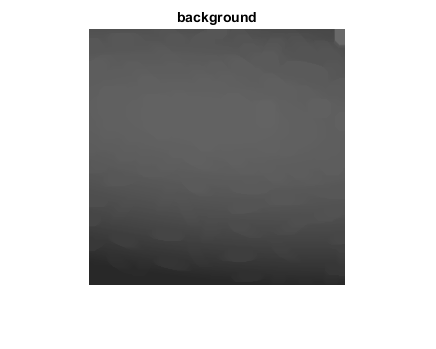


%No funciona, perdem grans. No confieu mai en els detectors automatics de llindar.
%El problema està en que la iluminació no és gens homogènea

% Fem un filtratge morfològic
bg = imopen(orig,strel('disk',10));
figure, imshow(bg),title('background')

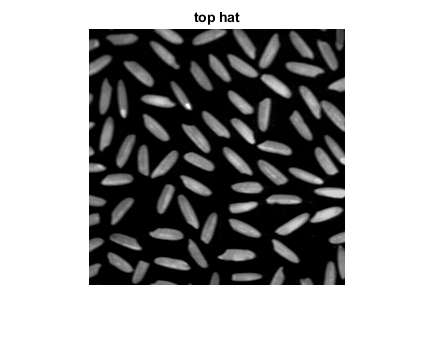

figure, surf(bg) % mostrem el background com si fos una superfície
%Li restem el background a la imatge
y = imsubtract(orig,bg);
figure, imshow(y, []), title( 'top hat')

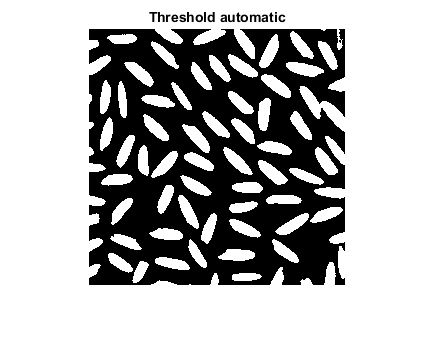

% tornem a segmentar per Otsu
bw=im2bw(y, graythresh(y));
figure, imshow(bw),title('Threshold automatic')

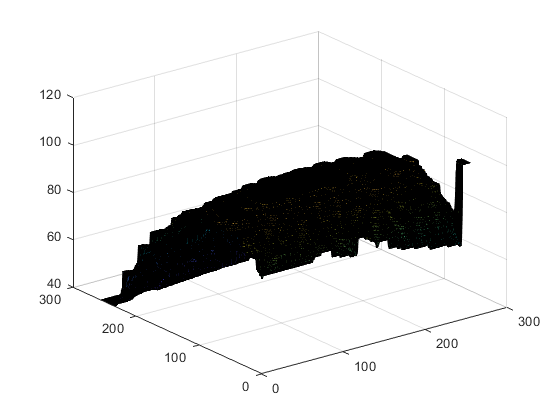

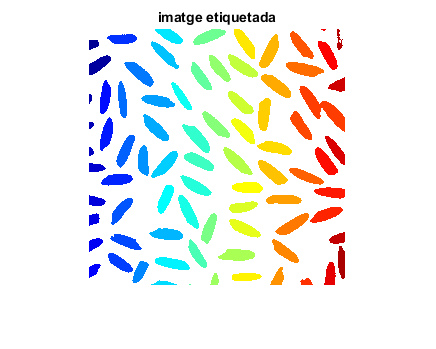

%Ara si!

% etiquetem la imatge segmentada
[eti num] = bwlabel(bw,4);
figure,imshow(label2rgb(eti)), title('imatge etiquetada')

% Comptem ara el nombre d’objectes a la imatge
num

num = 81

%o be:
max(eti(:))

ans = 81

% obtenim descriptors de les regions
Dades=regionprops(eti,'all');
%Comproveu en el workspace la variable Dades. Quines propietats hem extret de cada regió?
%Consulteu el help de la funció regionprops.

Hem obtingut l'area, el centroid, el BoundingBox, Subarrayldx, MajorAxisLength, MinorAxisLength, eccentricity, Orientation, ConvexHull, ConvexImage, ConvexArea, Circularity, Image, FilledImage, FilledArea, EulerNumber, Extrema, EquivDiameter, Solidity, Extent, PicelIdxList, PixelList, Perimeter, PerimeterOld, MaxFeretAngle, MaxFeretCoordinates, MinFeretDiameter, MinFeretAngle, MinFeretCoordinates.

% Podem obtenir una dada de l’objecte 50 de la forma:
Dades(50).Area

ans = 305

% O be un vector amb totes les Àrees:
Arees=[Dades.Area];

## Exercici 1

Exercici: en la imatge segmentada, separeu els grans d’arròs que es toquen. Desprès elimineu els grans d’arròs que toquen les vores. Tots aquests grans falsejaven el resultat. Amb la nova imatge etiquetatda, obteniu les propietats que us semblin adients usant regionprops. Representeu mitjançant plots o diagrames de barres aquelles propietats que us semblin interessants per a fer un control de qualitat dels grans d’arròs.

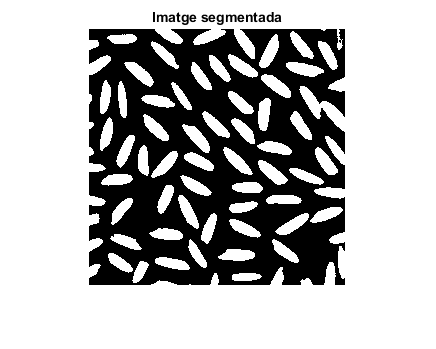

figure, imshow(bw),title('Imatge segmentada')

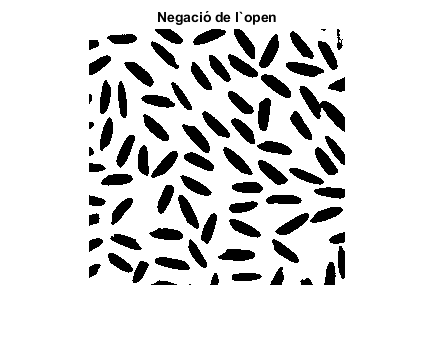

bw1= imcomplement(bw);
imshow(bw1);
title('Negació de l`open')

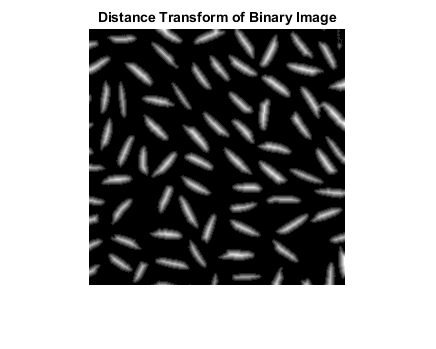


D = bwdist(~bw);
imshow(D,[])
title('Distance Transform of Binary Image')

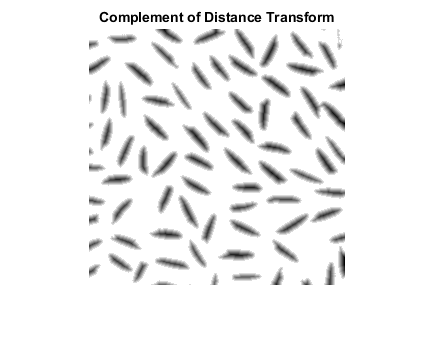



D = -D;
imshow(D,[])
title('Complement of Distance Transform')

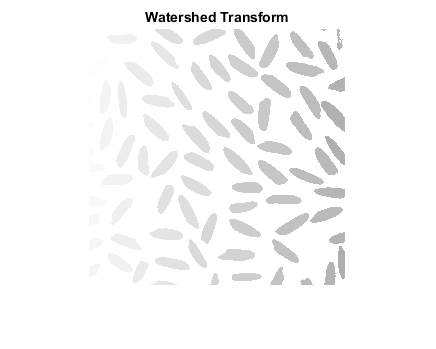


%Suprimim tots els minims amb profunditat menor que 1 de la imatge D.
D1=imhmin(D,1);
L = watershed(D1);
L(~bw) = 0;
imshow(imcomplement(L))
title('Watershed Transform')

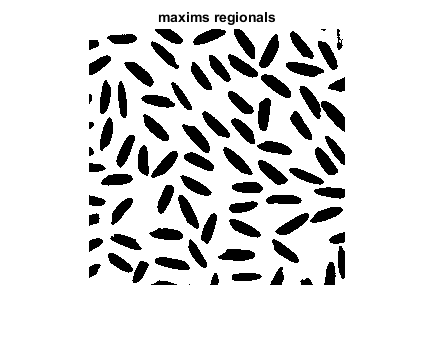



im2=imcomplement(L);
rm=imregionalmax(im2);
figure,imshow(rm),title('maxims regionals');

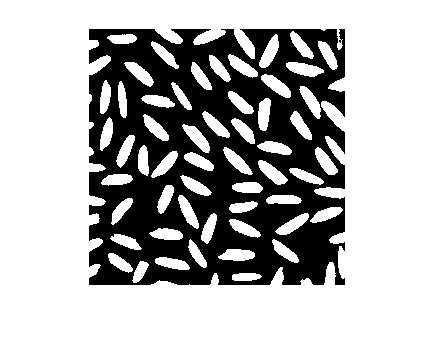

segm = imcomplement(rm);
imshow(segm)

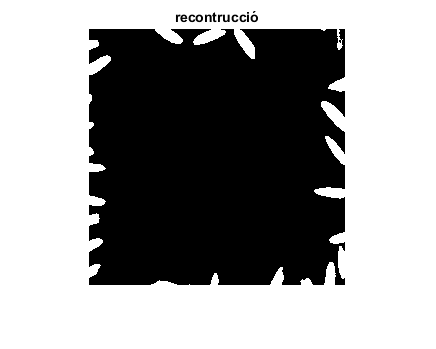


mark=true(256);
mark(2:end-1,2:end-1)=0;

rec=imreconstruct(mark,segm);
figure,imshow(rec),title('recontrucció')

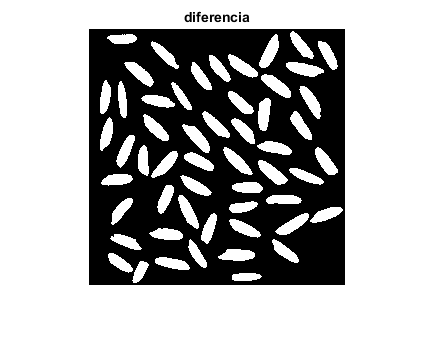


im2 = xor(rec,segm);
figure,imshow(im2),title('diferencia')

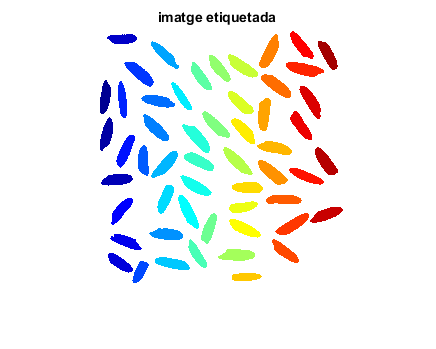



[eti1 num1] = bwlabel(im2,4);
figure,imshow(label2rgb(eti1)), title('imatge etiquetada')

% Comptem ara el nombre d’objectes a la imatge
num1

num1 = 54

% obtenim descriptors de les regions
Dades=regionprops(eti1,'all');

% La propietat de l'area de cada gran d'arros ens sembla interesant
Arees=[Dades.Area]

Arees =    269   278   284   236   252   271   272   306   250   339   206   264   290   322   304   283   317   300   281   220   331   305   357   307   242   275   281   316   275   339   339   331   291   239   305   296   283   203   317   328   355   354   354   281   281   338   365   279   292   299


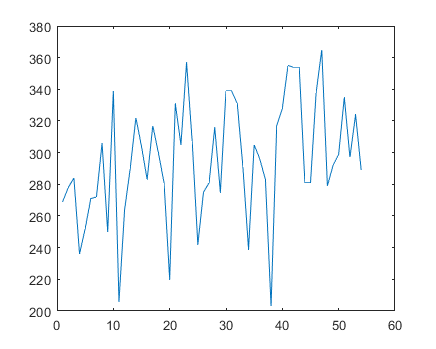

plot(Arees)

mean(Arees)

ans = 295.3148


% La propietat de MajorAxisLength i MinorAxisLength ens interessa perque
% sabem els rangs de tamany de cada gra d'arros.
Major=[Dades.MajorAxisLength]

Major =    34.1454   33.4122   32.3537   30.3216   30.0630   32.5210   32.9782   36.3770   38.0818   36.3565   25.3071   31.3634   34.0698   35.4319   33.6085   37.5361   36.1336   37.0459   31.8524   34.5131   38.4465   35.0086   37.9577   33.7683   32.6218   33.6722   32.5825   36.9406   33.1179   36.4467   38.5445   36.3317   33.2645   30.3035   35.1045   33.4333   31.8017   31.1438   35.3175   34.8753   36.3663   37.2839   36.8032   37.6251   34.3811   38.6849   38.6120   37.7482   34.8991   34.4504


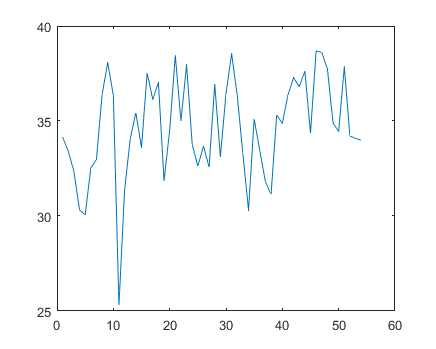

plot(Major)

mean(Major)

ans = 34.6510


Minor=[Dades.MinorAxisLength]

Minor =    10.2338   10.7958   11.3416   10.1916   10.8257   10.9652   10.8624   10.8760    8.4392   12.0595   10.6524   11.1410   10.9740   11.7302   11.6939    9.7797   11.4212   10.4514   11.4167    8.2618   11.1100   11.2794   12.2842   11.7664    9.6997   10.6200   11.2345   11.0964   10.7380   12.1623   11.3185   11.8749   11.3673   10.3280   11.2148   11.5046   11.4791    8.4082   11.7111   12.2969   12.6942   12.3661   12.3857    9.7787   10.6768   11.3622   12.2885    9.5230   10.9113   11.4433


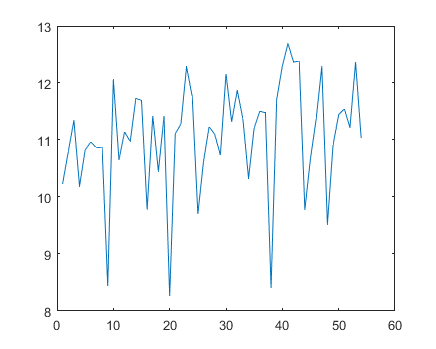

plot(Minor)

mean(Minor)

ans = 11.0591


%La propietat Eccentricity, que és la relació de la distància entre els
%focus de la el·lipse i la seva longitud dels eixos principals.
Ecc=[Dades.Eccentricity]

Ecc =     0.9540    0.9464    0.9365    0.9418    0.9329    0.9414    0.9442    0.9543    0.9751    0.9434    0.9071    0.9348    0.9467    0.9436    0.9375    0.9655    0.9487    0.9594    0.9336    0.9709    0.9573    0.9467    0.9462    0.9373    0.9548    0.9490    0.9387    0.9538    0.9460    0.9427    0.9559    0.9451    0.9398    0.9401    0.9476    0.9389    0.9326    0.9629    0.9434    0.9358    0.9371    0.9434    0.9417    0.9656    0.9506    0.9559    0.9480    0.9677    0.9499    0.9432


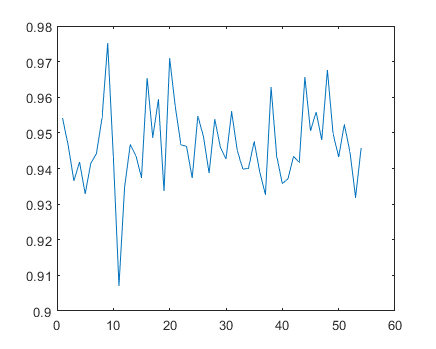

plot(Ecc)

mean(Ecc)

ans = 0.9465


%La propietat de Circularity també ens resulta interesant, ja que ens diu
%el grau de circularitat que té un gra d'arros.
Cir=[Dades.Circularity]

Cir =     0.6481    0.6521    0.7249    0.6816    0.7510    0.6191    0.6831    0.6579    0.5344    0.6907    0.8135    0.7294    0.6650    0.6905    0.7007    0.5617    0.6696    0.6405    0.7531    0.5566    0.6332    0.6585    0.6629    0.7450    0.6428    0.6729    0.7174    0.6470    0.6924    0.6646    0.6248    0.6778    0.7348    0.7245    0.6739    0.7129    0.7651    0.6296    0.6862    0.7308    0.7218    0.6981    0.7217    0.6066    0.6624    0.6450    0.6566    0.5841    0.6611    0.6996


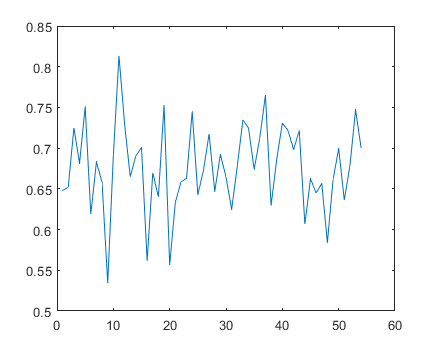

plot(Cir)

mean(Cir)

ans = 0.6767


%Per últim, ens resultava interesant tenir en compte el perimetre de cada
%gra d'arròs.
Per=[Dades.Perimeter]

Per =    72.2230   73.1910   70.1640   65.9630   64.9380   74.1670   70.7360   76.4500   76.6720   78.5350   56.4110   67.4430   74.0260   76.5500   73.8360   79.5690   77.1290   76.7220   68.4770   70.4790   81.0480   76.2930   82.2650   71.9590   68.7840   71.6620   70.1560   78.3450   70.6450   80.0630   82.5710   78.3360   70.5460   64.3830   75.4160   72.2330   68.1790   63.6550   76.1930   75.1010   78.6180   79.8240   78.5100   76.3000   73.0100   81.1480   83.5780   77.4750   74.4990   73.2830


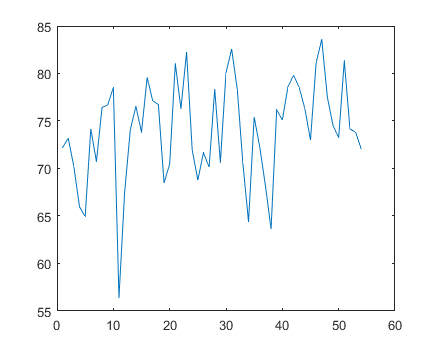

plot(Per)

mean(Per)

ans = 74.0581

## 2. Codis de cadena

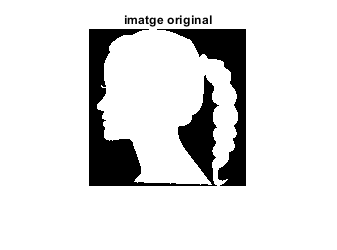

clear all, close all
im=imread('head.png');
% no cal tan gran
im=imresize(im,1/4);
imshow(im), title('imatge original')

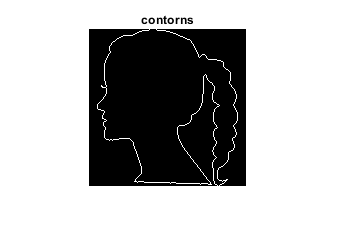

% obtenim el contorn
ero=imerode(im,strel('disk',1));
cont=xor(ero,im);
figure,imshow(cont), title('contorns')

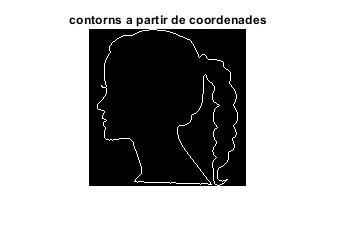

% obtenim les coordenades del contorn
[fila col] = find(im,1); % Busquem el primer píxel
B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
% B conté les coordenades
% Ho comprovem mostrant el resultat
aux=zeros(size(im));
aux(sub2ind(size(aux),B(:,1),B(:,2)))=1;
figure,imshow(aux),title ('contorns a partir de coordenades')

## Exercici 2

Trobar els codis de cadena incrementals a partir de B

incremental = zeros(754,1);

% W -> 1 
% NW -> 2
% N -> 3
% NE -> 4
% E -> 5
% SE -> 6
% S -> 7
% SW -> 8

W1 = [-1,0];
NW1 = [-1,1];
N1 = [0,1];
NE1 = [1,1];
E1 = [1,0];
SE1 = [1,-1];
S1 = [0,-1];
SW1 = [-1,-1];

prev = B(1,:);

for v = 2:length(B)
    K = B(v,:) - prev;
    if (K == W1)
        incremental(v-1) = 1;
    end
    
    if (K == NW1)
        incremental(v-1) = 2;
    end
    
    if (K == N1)
        incremental(v) = 3;
    end
    
    if (K == NE1)
        incremental(v-1) = 4;
    end
    
    if (K == E1)
        incremental(v-1) = 5;
    end
    
    if (K == SE1)
        incremental(v-1) = 6;
    end
    
    if (K == S1)
        incremental(v-1) = 7;
    end
    
    if (K == SW1)
        incremental(v-1) = 8;
    end
    prev = B(v,:);
end


r = zeros(754,1);

for k = 2:754
    r(k) = rotation(incremental(k-1),incremental(k));
end

## 3. Descriptors de Fourier

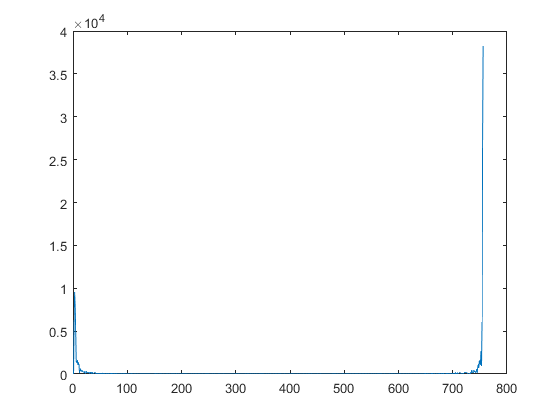

% centrem coordenades
mig=mean(B);
B(:,1)=B(:,1)-mig(1);
B(:,2)=B(:,2)-mig(2);
% Convertim les coordenades a complexes
s= B(:,1) + i*B(:,2);
% Cal que la dimensio del vector sigui parell
[mida bobo]=size(B);
if(mida/2~=round(mida/2))
s(end+1,:)=s(end,:); %dupliquem l'ultim
mida=mida+1;
end
% Calculem la Fast Fourier Transform
z=fft(s);
% representem l’espectre
figure,plot(abs(z))

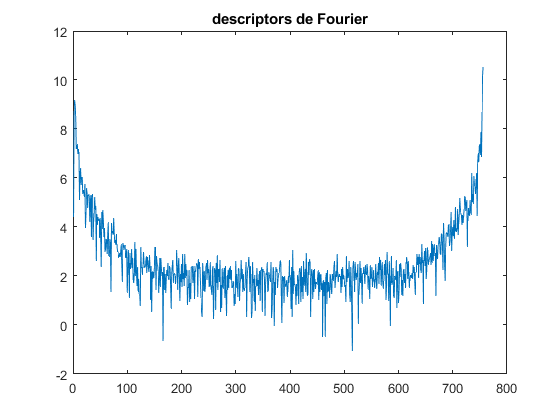

% ho displaiem logaritmic perque no es veu res
figure,plot(log(abs(z))), title ('descriptors de Fourier')

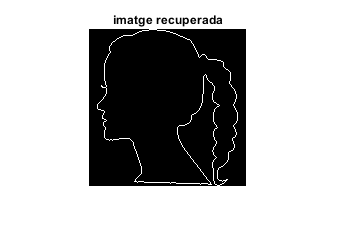

% Recuperem la imatge original per comprovar que el procés és reversible
ss=ifft(z); % Transformada de Fourier inversa
files= round(real(ss)+mig(1));
cols=round(imag(ss)+mig(2));
aux(:,:)=0;
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux), title('imatge recuperada')

## Reduim la quantitat de descriptors de Fourier

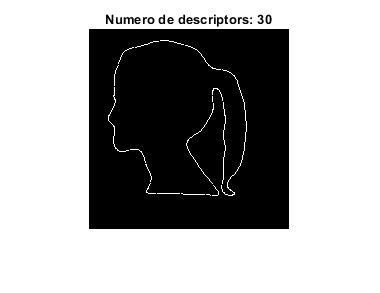

N=30; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 30 descriptors')
% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)
title(['Numero de descriptors: ',num2str(N)]);

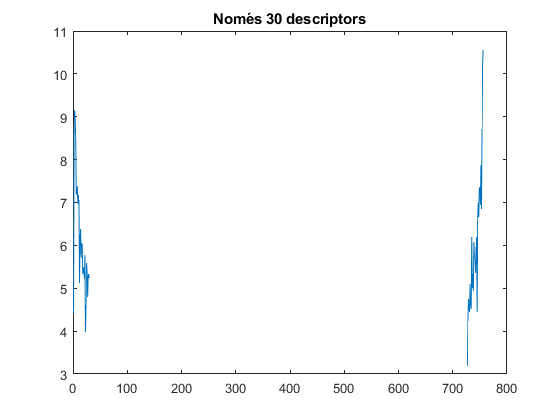


N=15; % agafem  descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 30 descriptors')
% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)

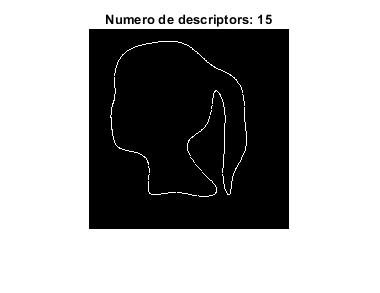

title(['Numero de descriptors: ',num2str(N)]);

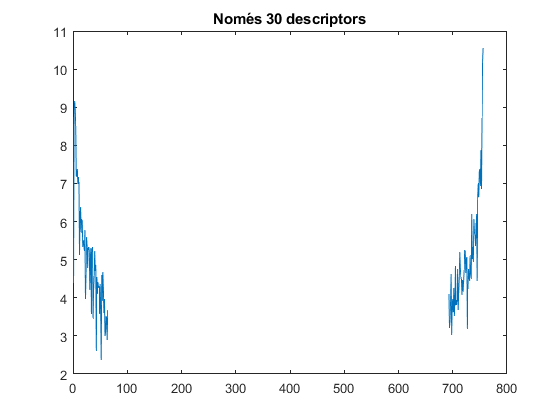


N=64; % agafem 100 descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 30 descriptors')

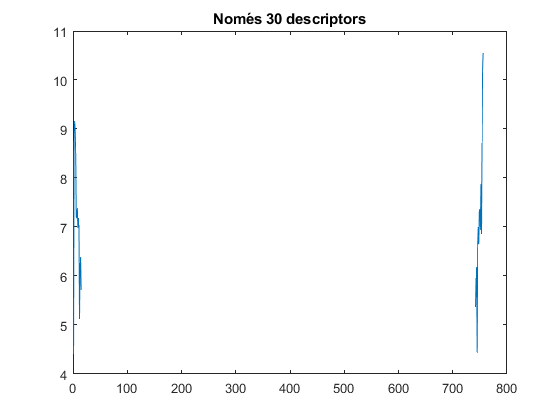

% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)

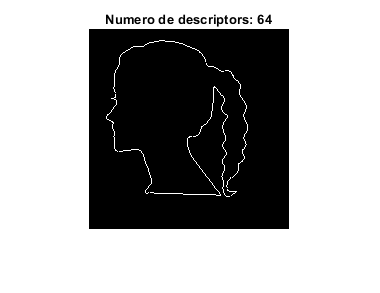

title(['Numero de descriptors: ',num2str(N)]);

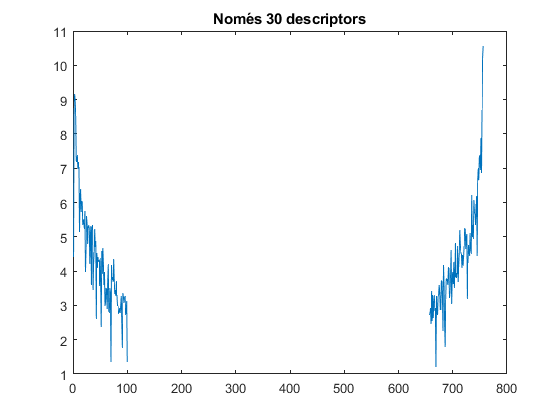


N=100; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
figure, plot(log(abs(tmp))), title ('Només 30 descriptors')

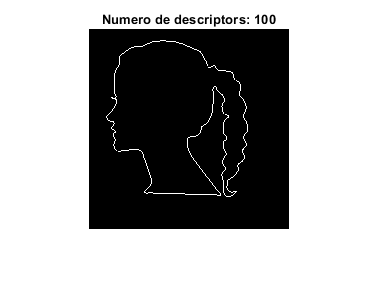

% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);
% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=200;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)
title(['Numero de descriptors: ',num2str(N)]);


%El que fem es agafar N components de Fourier i sabem que quantes més
%components de Fourier agafem amb més detall es veure l'objecte ja que les
%components amb freqüéncies més baixes defineixen els detalls de l'objecte.
%Partint de la imatge base amb 30 descriptors es pot identificar que quan
%menys descriptors perdem detall de la imatge i amb més al contrari fins a
%un límit ja que en algun valor ya no augmentará el detall de la imatge.

## Funció Exercici 2 per nombrar els girs de la cadena de codi incremental


function [rot] = rotation(dir1, dir2)
    rot = dir2 - dir1;
    if(rot == -7) 
        rot = 1; 
    end
    if (rot == -6)
        rot = 2;
    end
    if (rot == -5)
        rot = 3;
    end
    if (rot == -4)
        rot = 4;
    end
    if (rot == -3)
        rot = 5;
    end
    if (rot == -2)
        rot = 6;
    end
    if (rot == -1)
        rot = 7;
    end
end